## EEL839 - Transmissão Digital

## Parte 2 - Treinamento da rede neural e ataque FGSM

Trabalho sobre o artigo: Adversarial training based channel estimation to mitigate jamming attacks in OFDM systems

Guilherme Araujo Thomaz

Este código implementa a parte do trabalho referente à geração de gráficos.

## 1 - Estimação por LS

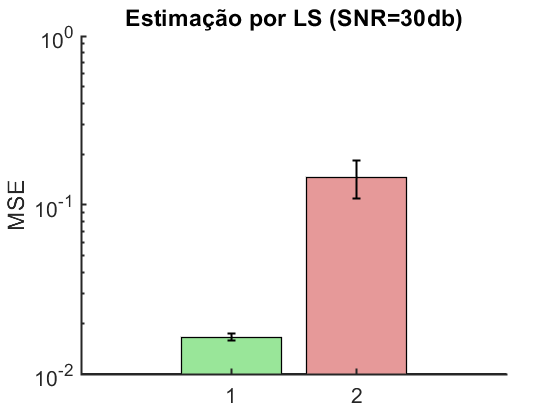

%X = categorical({'Pubicação insegura','Publicação segura','Consulta insegura','Consulta segura'});
%X = reordercats(X,{'Pubicação insegura','Publicação segura','Consulta insegura','Consulta segura'});
X = [1 2];
Y = [0.0165 0.1454];
erro = [7.93e-4 0.0368];
hbar = bar(X,Y,'FaceColor','flat');
hbar.CData(2,:) = [.9 0.6 .6];
hbar.CData(1,:) = [.6 0.9 .6];
hbar.LineWidth = 1;
ylim([10e-3 1])
set(gca,'YScale','log')
hold on
err = errorbar(Y,erro);
err.LineWidth = 1.5;
err.Color = [0 0 0];
err.LineStyle = 'none';
t = title('Estimação por LS (SNR=30db)');
t.FontSize = 16;
yl = ylabel('MSE');
yl.FontSize = 16;
yl.FontSize = 16;
H=gca;
H.LineWidth = 1.5;
set(gca,'FontSize',16)
box off
hold off

## 2 - Rede neural vulnerável

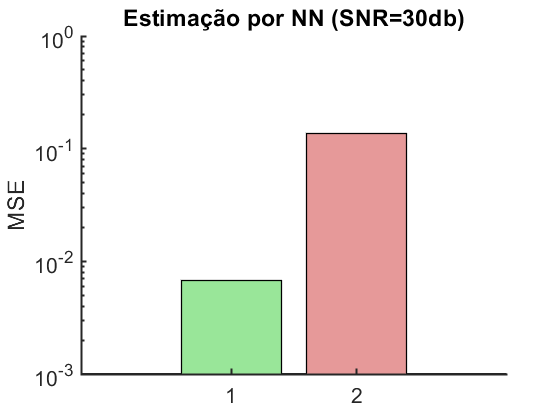

%X = categorical({'Pubicação insegura','Publicação segura','Consulta insegura','Consulta segura'});
%X = reordercats(X,{'Pubicação insegura','Publicação segura','Consulta insegura','Consulta segura'});
X = [1 2];
Y = [0.0068 0.1356];
hbar = bar(X,Y,'FaceColor','flat');
hbar.CData(2,:) = [.9 0.6 .6];
hbar.CData(1,:) = [.6 0.9 .6];
hbar.LineWidth = 1;
ylim([10e-4 1])
set(gca,'YScale','log')
hold on
t = title('Estimação por NN (SNR=30db)');
t.FontSize = 16;
yl = ylabel('MSE');
yl.FontSize = 16;
yl.FontSize = 16;
H=gca;
H.LineWidth = 1.5;
set(gca,'FontSize',16)
box off
hold off